## Ejercicio 3 (2 puntos). Dado el sistema físico conocido como “Pelota sobre barra” cuya función de transferencia es $G\left(s\right)=\frac{m\;d\;g}{\frac{L\left(J+m\;R^2 \right)}{R^2 }s^2 }$. Con parámetros: m=0.1kg; R=0.015m; g=9.8m/s2; L=1m; d=0.03m; J=10−6 kg·m2. Haciendo uso de las herramientas de diseño y análisis de Matlab, diseñe un controlador para que el sistema presente un tiempo de establecimiento menor a 3.5 segundos y un pico máximo inferior al 10%, según el siguiente diagrama de control:

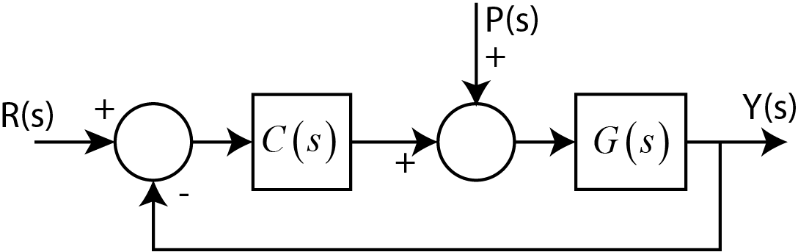

m=0.1;
R=0.015;
g=9.8;
L=1;
d=0.03;
J=1e-6;
%Función de transferencia del sistema
G=tf(m*d*g, [L*(J+m*R^2)/R^2, 0, 0])

G =
 
    0.0294
  ----------
  0.1044 s^2
 
Continuous-time transfer function.
Model Properties


a) Analice el lugar de las raíces del sistema y exponga los criterios de selección del controlador en función de las diferentes gráficas y datos que considere relevantes. En base a estos, diseñe el controlador del tipo seleccionado y exponga las gráficas que considere necesarias incluyendo, LDR, respuesta paso, y una captura de pantalla del ambiente RLTOOL donde se vea claramente el tipo de herramientas de calibración utilizadas (para el ajuste del controlador y para los criterios de diseño) (1 pto).

rltool(G)

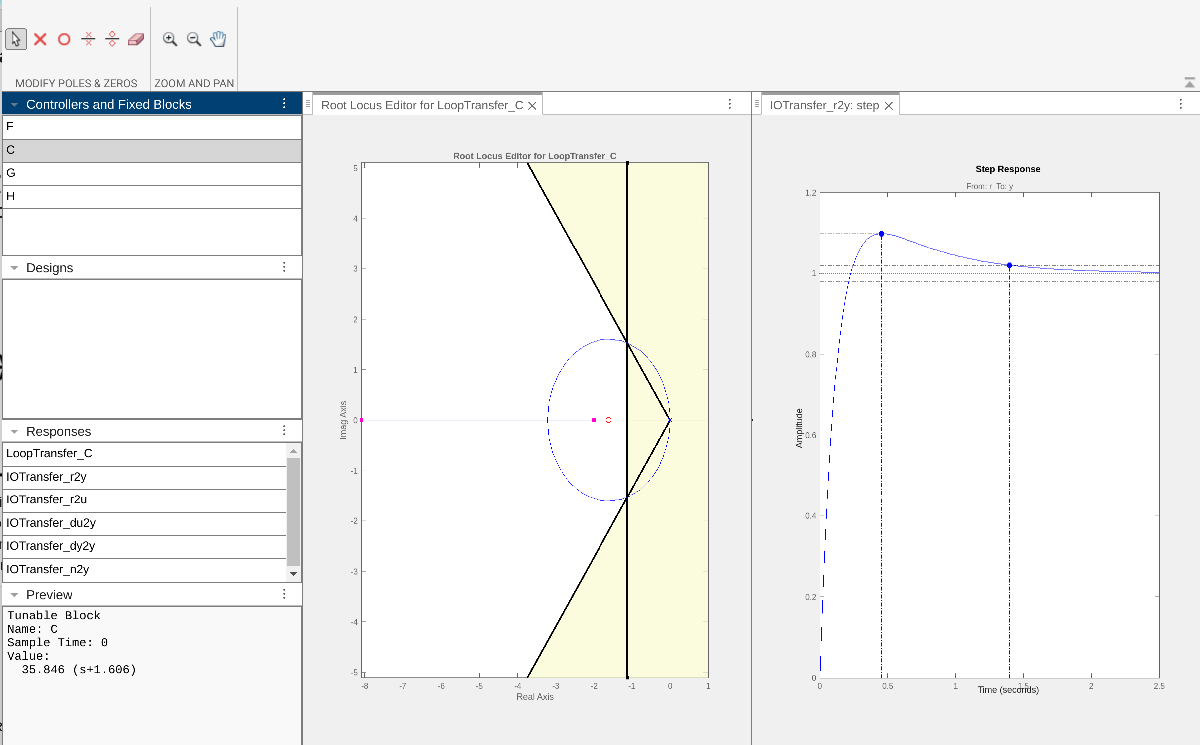

El controlador creado para controlar el sistema ha sido un  PD, ya que era el mas sencillo de la familia de los PID que conseguia cumplir con las condiciones del tiempo de establecimiento menor que 3.5 segundos y del pico maximo menor que el 10%. Ya que la posicion del cero no es despreciable en el comportamiento del sistema las zonas delimitadas en amarillo (zonas no validas) no representan el fielmente el comportamiento del sistema ante una entrada escalon.

b) Analice la respuesta del sistema en lazo cerrado frente a una perturbación de tipo impulso y tipo paso (0.5 ptos).

Para analizar la respuesta ante la perturbación, el controlador pasaría a estar en la realimentación del lazo de control. Luego queda:

C = tf(35.846*[1 1.606],1) % Defino el controlador

C =
 
  35.85 s + 57.57
 
Continuous-time transfer function.
Model Properties


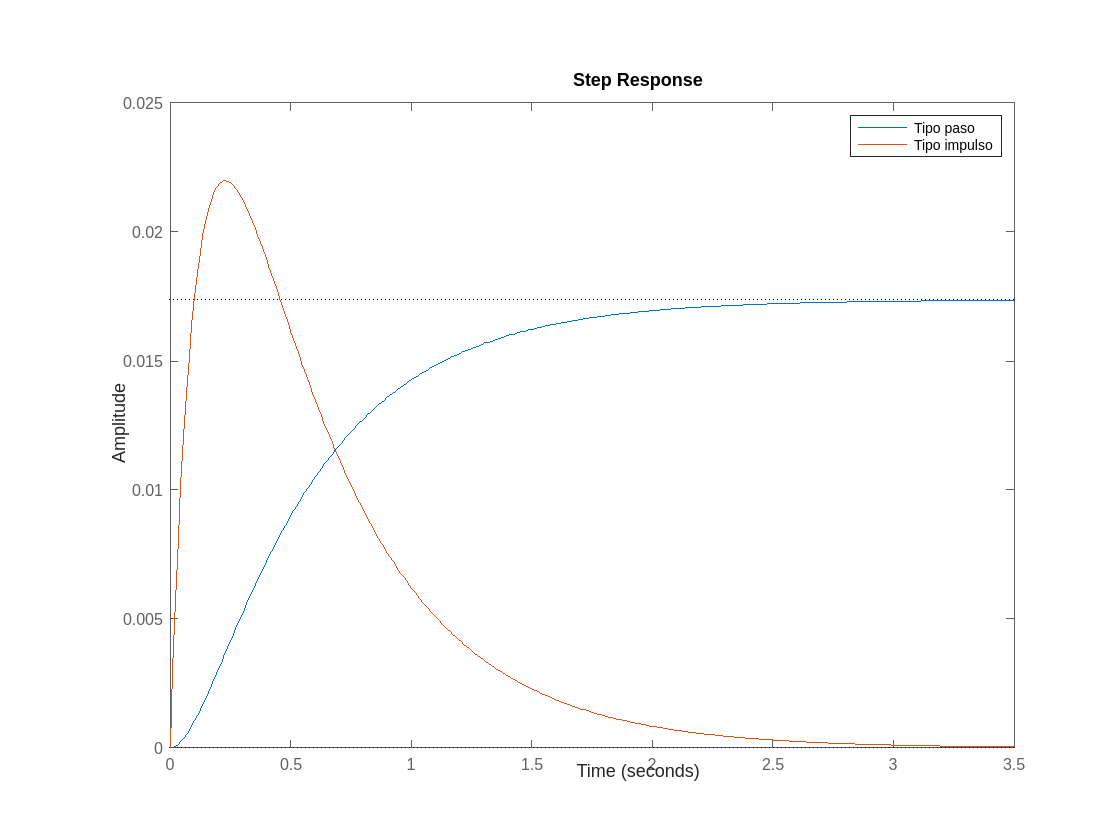


G_pert=feedback(G, C, -1);

figure();
hold on
step(G_pert)
impulse(G_pert)
hold off
legend('Tipo paso', 'Tipo impulso')

Podemos observar que ante la perturbacion de tipo impulso el sistema presenta 'overshoot' en el impulso, pero luego el error vuelve rapidamente a 0. Esto no ocurre ante la entrada de tipo paso, con la que no sera capaz de quitar el error.

c) Diseñe un controlador tal que mantenga las características en el régimen transitorio anterior y anule el error frente a una perturbación de tipo paso (0.5 ptos).

Para anular el error frente a una perturbación de tipo paso habra que añadirle una parte integral al controlador anterior, convirtiendolo en un PID.

rltool(G)

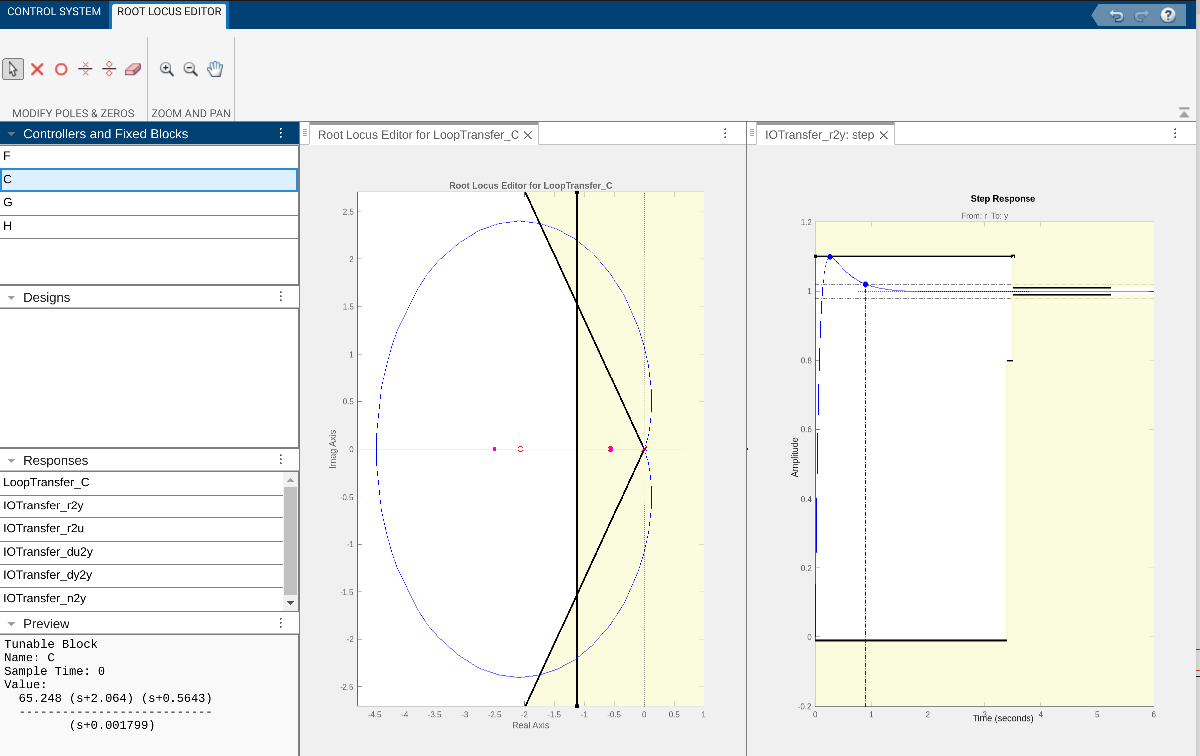

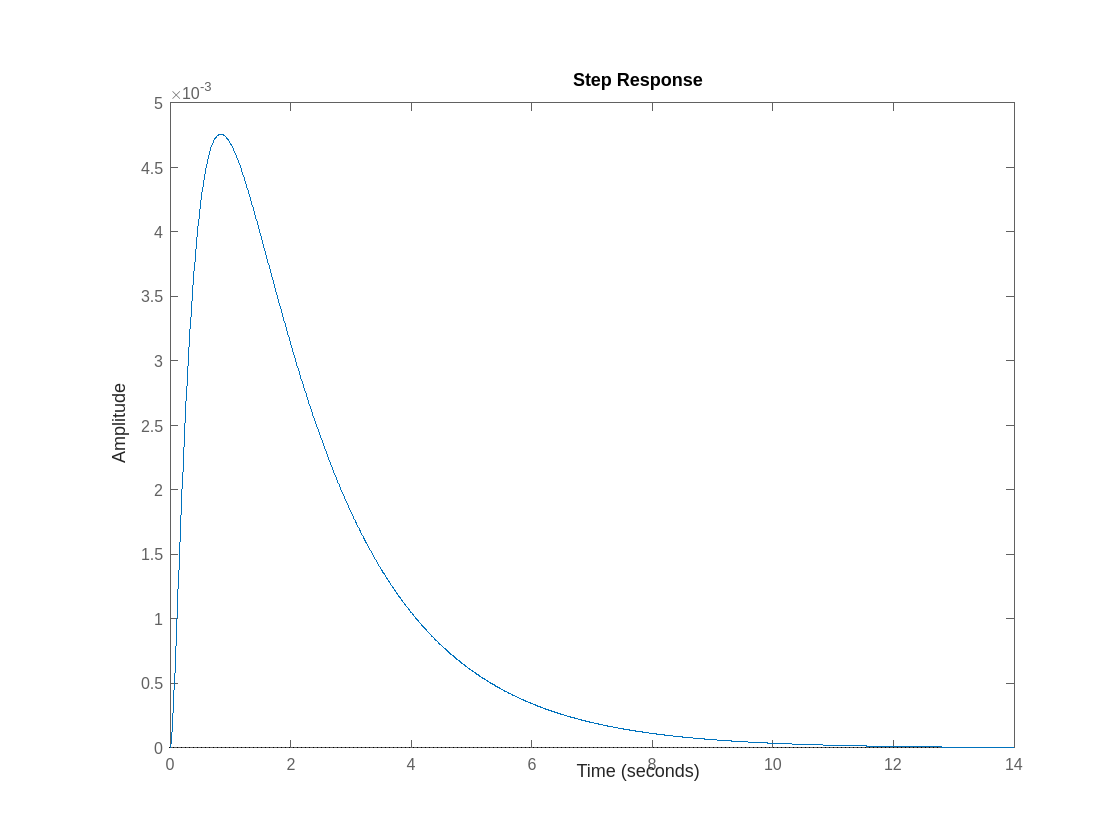

C_PID=zpk([-0.5643, -2.064], [0], 65.248); % Pongo el polo en 0 a mano porque en rltool es complicado
G_pert_PID=feedback(G, C_PID, -1);
step(G_pert_PID)

Como se puede ver ahora el controlador es capaz de subsanar el error ante este tipo de perturbaciones.